# Plot M3C Variables

buffer

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 2000
                  m: 9
                  n: 4
                  A: [6×9 double]
                 is: [9×2000 double]
                ixy: [6×2000 double]
                 iB: [9×2000 double]
                 iz: [9×2000 double]
                 ie: [4×2000 double]
                 vs: [9×2000 double]
                vxy: [6×2000 double]
                 vB: [9×2000 double]
                 vo: [59.5741 -46.0957 52.7870 85.7377 102.1549 121.1146 126.6349 128.9066 126.5049 123.4062 114.5729 98.3222 77.4904 71.7906 79.6204 91.7048 103.3807 113.2103 120.9132 126.4893 130.0582 131.8210 132.0412 131.0344 … ] (1×2000 double)
                 Ec: [9×2000 double]
                 vc: [9×2000 double]
            Ec_mean: [8.0935e+05 8.0931e+05 8.0927e+05 8.0922e+05 8.0919e+05 8.0916e+05 8.0912e+05 8.0909e+05 8.0910e+05 8.0916e+0

clf

## is

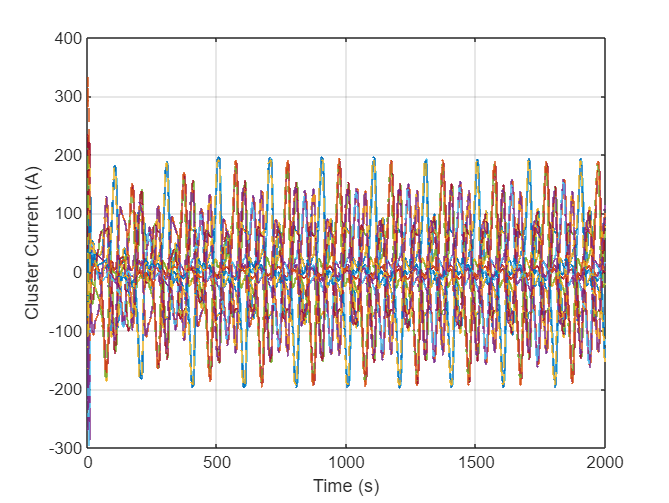

figure
stairs(buffer.is')
hold on
stairs(buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

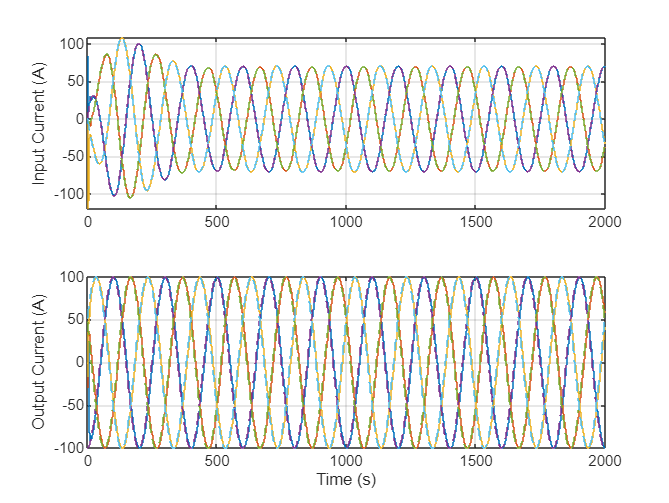

figure
subplot(2, 1, 1)
stairs(buffer.ixy(1:3, :)')
hold on
stairs(buffer.ixy_ref(1:3, :)', '--')
hold off

ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.ixy(4:6, :)')
hold on
stairs(buffer.ixy_ref(4:6, :)', '--')
hold off

xlabel('Time (s)')
ylabel('Output Current (A)')
grid on

## `iB`

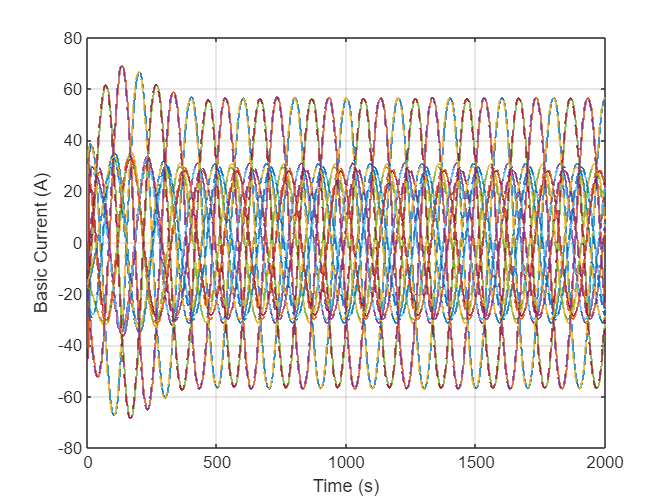

figure
stairs(buffer.iB')
hold on
stairs(buffer.iB_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Basic Current (A)')
grid on

## `iz`

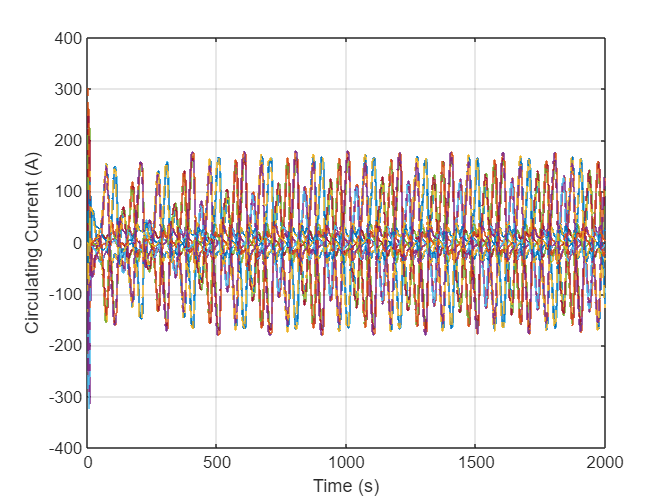

figure
stairs(buffer.iz')
hold on
stairs(buffer.iz_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Circulating Current (A)')
grid on

## `ie`

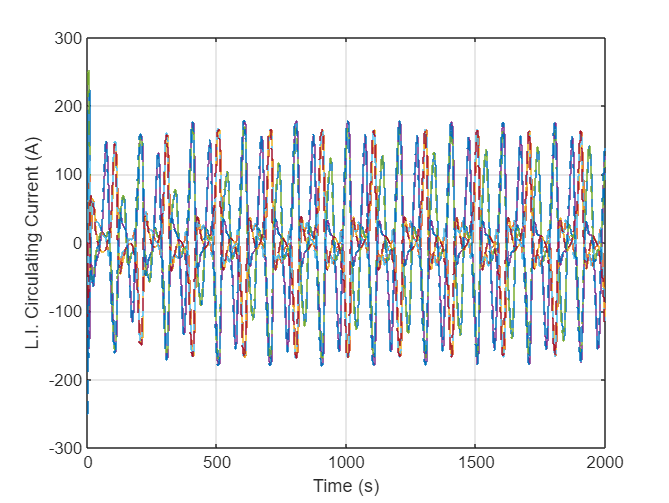

figure
stairs(buffer.ie')
hold on
stairs(buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vs`

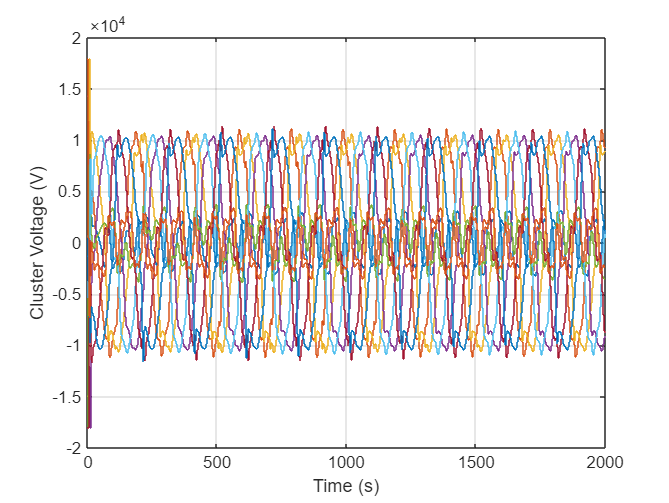

figure
stairs(buffer.vs')
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## `vxy`

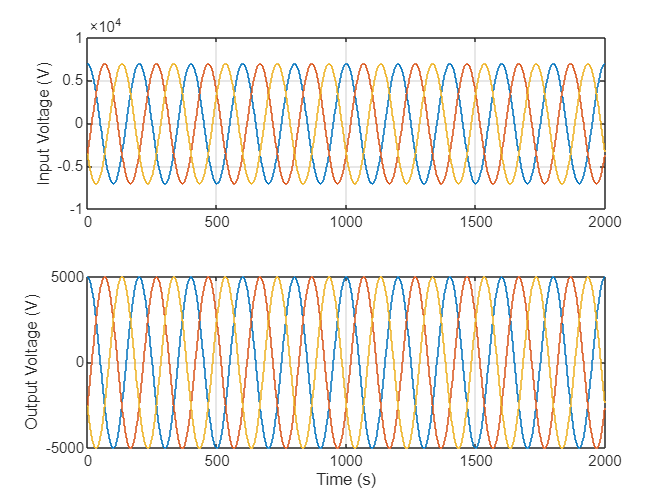

figure
subplot(2, 1, 1)
stairs(buffer.vxy(1:3, :)')

ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.vxy(4:6, :)')

xlabel('Time (s)')
ylabel('Output Voltage (V)')
grid on

## `vB`

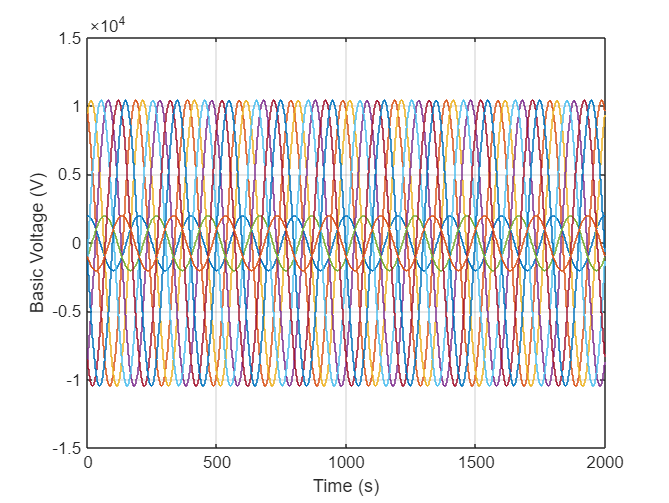

figure
stairs(buffer.vB')
xlabel('Time (s)')
ylabel('Basic Voltage (V)')
grid on

## `vo`

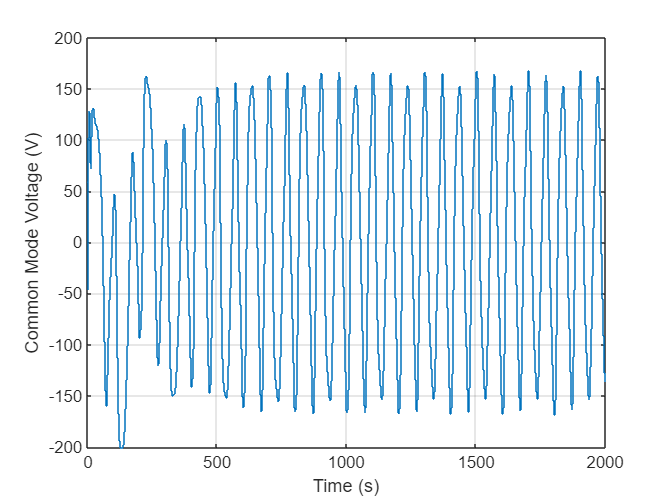

figure
stairs(buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## `Ec`

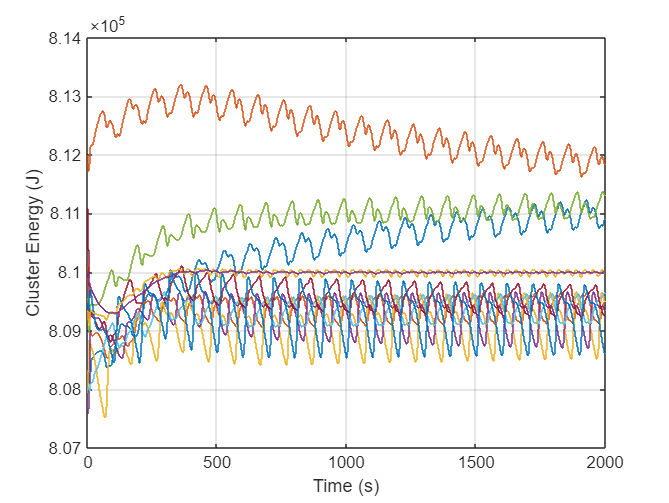

figure
stairs(buffer.Ec')
hold on
stairs(buffer.Ec_mean')
stairs(buffer.Ec_mean_filt')
hold off
ylabel('Cluster Energy (J)')
xlabel('Time (s)')
grid on

## `vc`

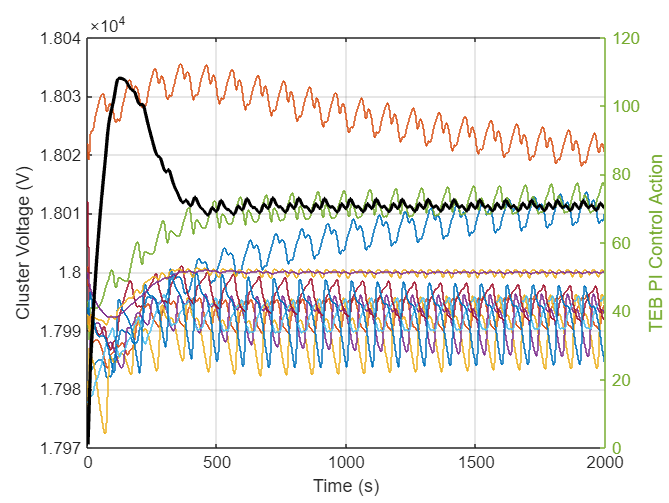

figure

stairs(buffer.vc')
hold on
stairs(buffer.vc_mean')
stairs(buffer.vc_mean_filt')
hold off
ylabel('Cluster Voltage (V)')

yyaxis right
stairs(buffer.u_TEB', 'LineWidth', 2, 'Color', 'black')
ylabel('TEB PI Control Action')

xlabel('Time (s)')
grid on

## Input PLL

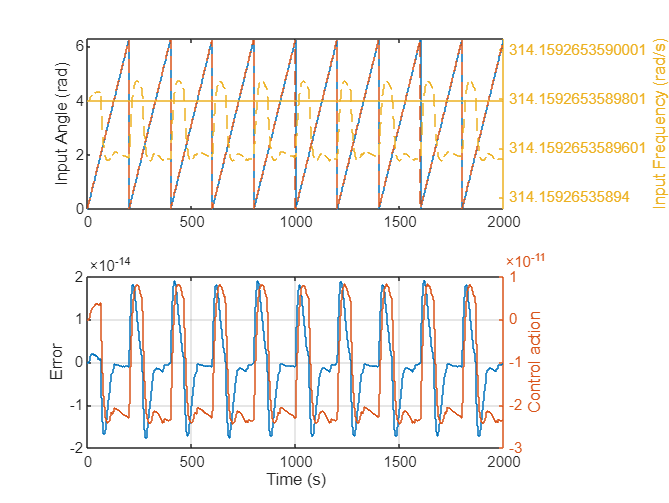

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.gx')
hold on
stairs(buffer.gx_pll', '--')
hold off
ylabel('Input Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.wx')
hold on
stairs(buffer.wx_pll', '--')
hold off
ylabel('Input Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.ex_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.ux_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Output PLL

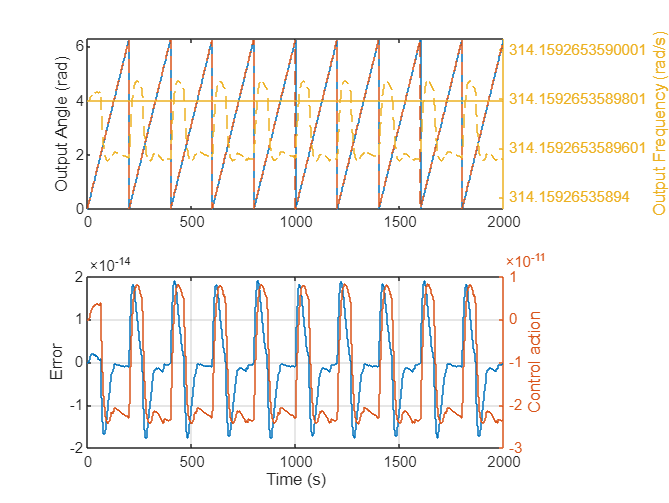

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.gy')
hold on
stairs(buffer.gy_pll', '--')
hold off
ylabel('Output Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.wy')
hold on
stairs(buffer.wy_pll', '--')
hold off
ylabel('Output Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.ey_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.uy_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Exit Flags

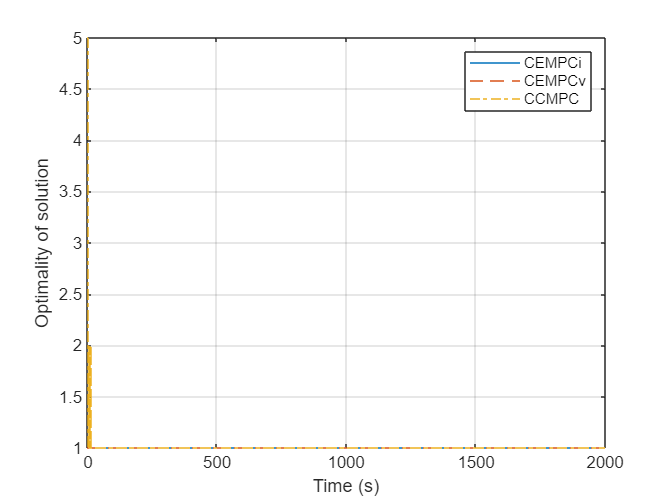

figure
stairs(buffer.exitflag_CEMPCi', '-')
hold on
stairs(buffer.exitflag_CEMPCv', '--')
stairs(buffer.exitflag_CCMPC', '-.')
hold off
ylabel('Optimality of solution')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Active Constraints

figure
stairs(buffer.iA_CEMPCi', '-')
hold on
stairs(buffer.iA_CEMPCv', '--')
stairs(buffer.iA_CCMPC', '-.')
hold off
ylabel('Number of active constraints')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on